# Through this example you will learn how to use MathWorks tools for various steps of a linear model predictive control workflow

## Linear MPC Workflow

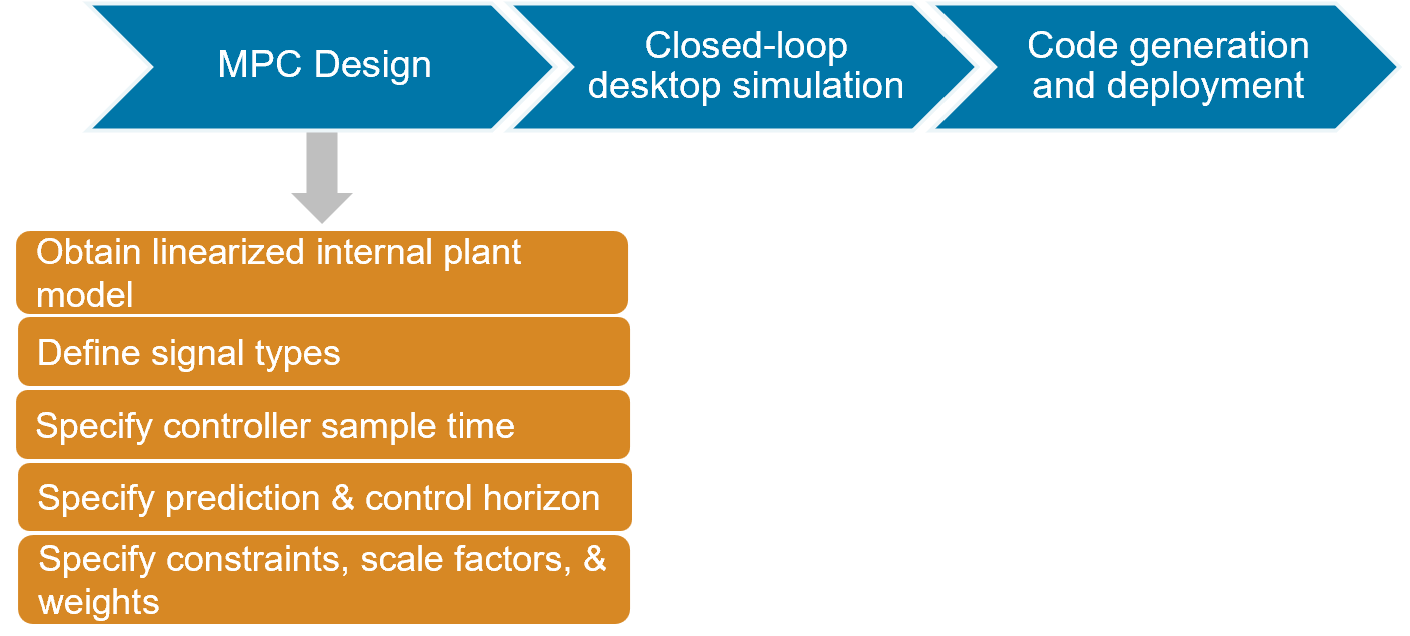

**Plant:** You will be using a simulation model of an inverted pendulum on a cart as your plant.

**Goal:** The model predictive controller (MPC) needs to keep the pendulum upright while moving the cart to a new position or when the pendulum is nudged forward by an impulse disturbance applied at the upper end of the inverted pendulum.

## Pendulum/Cart Assembly

The plant for this example is the following cart/pendulum assembly, where *x* is the cart position and *theta* is the pendulum angle.

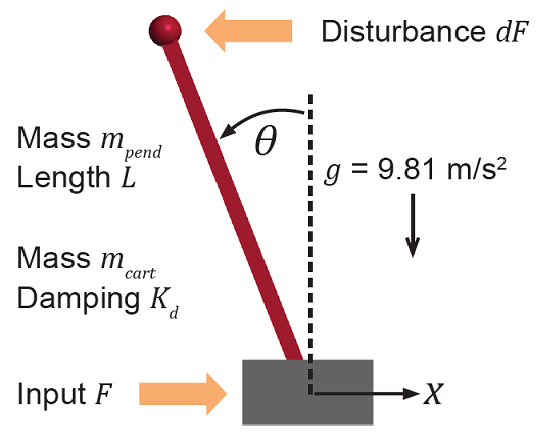

This system is controlled by exerting a variable force *F* on the cart. The controller needs to keep the pendulum upright while moving the cart to a new position or when the pendulum is nudged forward by an impulse disturbance *dF* applied at the upper end of the inverted pendulum.

This plant is modeled in Simulink with commonly used blocks.

clear;
cd(fileparts(which('ControlOfAnInvertedPendulumOnACartExample.mlx'))); % changing current folder

mdlPlant = 'mpc_pendcartPlant';
load_system(mdlPlant)
open_system([mdlPlant '/Pendulum and Cart System'],'force')

## Control Objectives

Assume the following initial conditions for the cart/pendulum assembly:

- The cart is stationary at *x* = `0`.

- The inverted pendulum is stationary at the upright position *theta* = `0`.

The control objectives are:

- Cart can be moved to a new position between `-10` and `10` with a step setpoint change.

- When tracking such a setpoint change, the rise time should be less than 4 seconds (for performance) and the overshoot should be less than `5` percent (for robustness).

- When an impulse disturbance of magnitude of `2` is applied to the pendulum, the cart should return to its original position with a maximum displacement of `1`. The pendulum should also return to the upright position with a peak angle displacement of `15` degrees (`0.26` radian).

The upright position is an unstable equilibrium for the inverted pendulum, which makes the control task more challenging.

## Control Structure

For this example, use a single MPC controller with:

- One manipulated variable: Variable force *F*.

- Two measured outputs: Cart position *x* and pendulum angle *theta*.

- One unmeasured disturbance: Impulse disturbance *dF*.

mdlMPC = 'mpc_pendcartImplicitMPC';
open_system(mdlMPC)

Although cart velocity *x_dot* and pendulum angular velocity *theta_dot* are available from the plant model, to make the design case more realistic, they are excluded as MPC measurements.

While the cart position setpoint varies (step input), the pendulum angle setpoint is constant (`0` = upright position). 

The Simulink model was already created for you. Please note the following:

-  "MPC Controller" block from the Model Predictive Control Toolbox is used in the model. More details regarding this block can be found in this [link](https://www.mathworks.com/help/mpc/ref/mpccontroller.html).

- If you double click the "MPC Controller" block, you can see that the `mpcobj `which you will be defining below is specified as a parameter.

- Step input for cart position setpoint, constant input for the pendulum angle, and impulse disturbance *dF* have been defined in the model. Please see the figures below.

Step input for cart position setpoint:

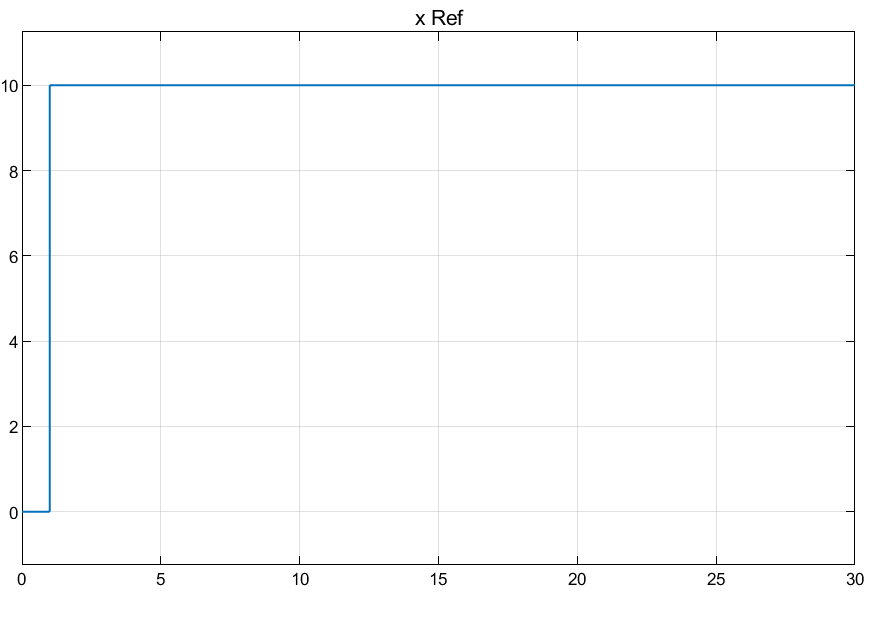

Impulse disturbance *dF*:

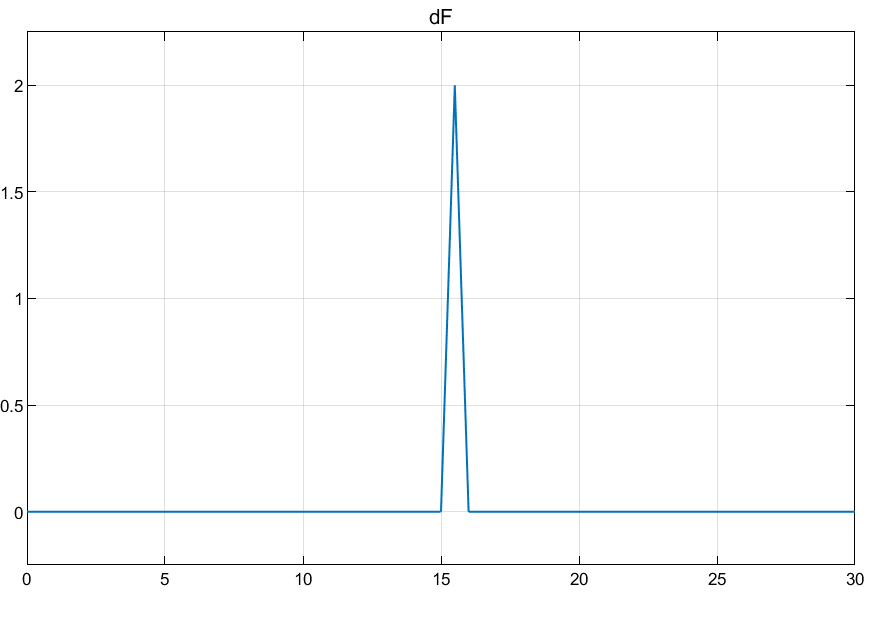

## Obtaining Linearized Internal Plant Model

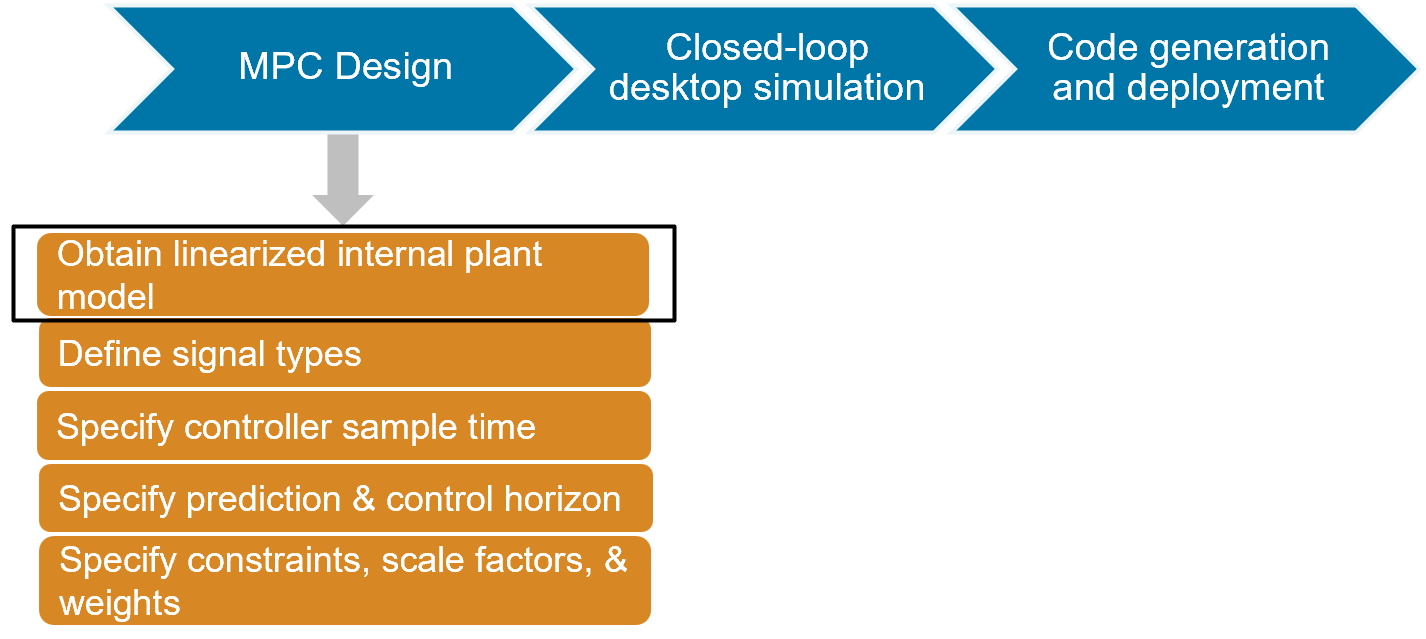

Since the MPC controller requires a linear time-invariant (LTI) plant model for prediction, linearize the Simulink plant model at the initial operating point.

Specify linearization input and output points.

io(1) = linio([mdlPlant '/dF'],1,'openinput');
io(2) = linio([mdlPlant '/F'],1,'openinput');
io(3) = linio([mdlPlant '/Pendulum and Cart System'],1,'openoutput');
io(4) = linio([mdlPlant '/Pendulum and Cart System'],3,'openoutput');

Create operating point specifications for the plant initial conditions.

opspec = operspec(mdlPlant);

The first state is cart position *x*, which has a known initial state of 0.

opspec.States(1).Known = true;
opspec.States(1).x = 0;

The third state is pendulum angle *theta*, which has a known initial state of 0.

opspec.States(3).Known = true;
opspec.States(3).x = 0;

Compute operating point using these specifications.

options = findopOptions('DisplayReport',false);
op = findop(mdlPlant,opspec,options);

Obtain the linear plant model at the specified operating point.

plant = linearize(mdlPlant,op,io);
plant.InputName = {'dF';'F'};
plant.OutputName = {'x';'theta'};

Examine the poles of the linearized plant.

pole(plant)

ans =          0
  -11.9115
   -3.2138
    5.1253


The plant has an integrator and an unstable pole. Closing the plant simulation file.

bdclose(mdlPlant)

## Define Signal Types

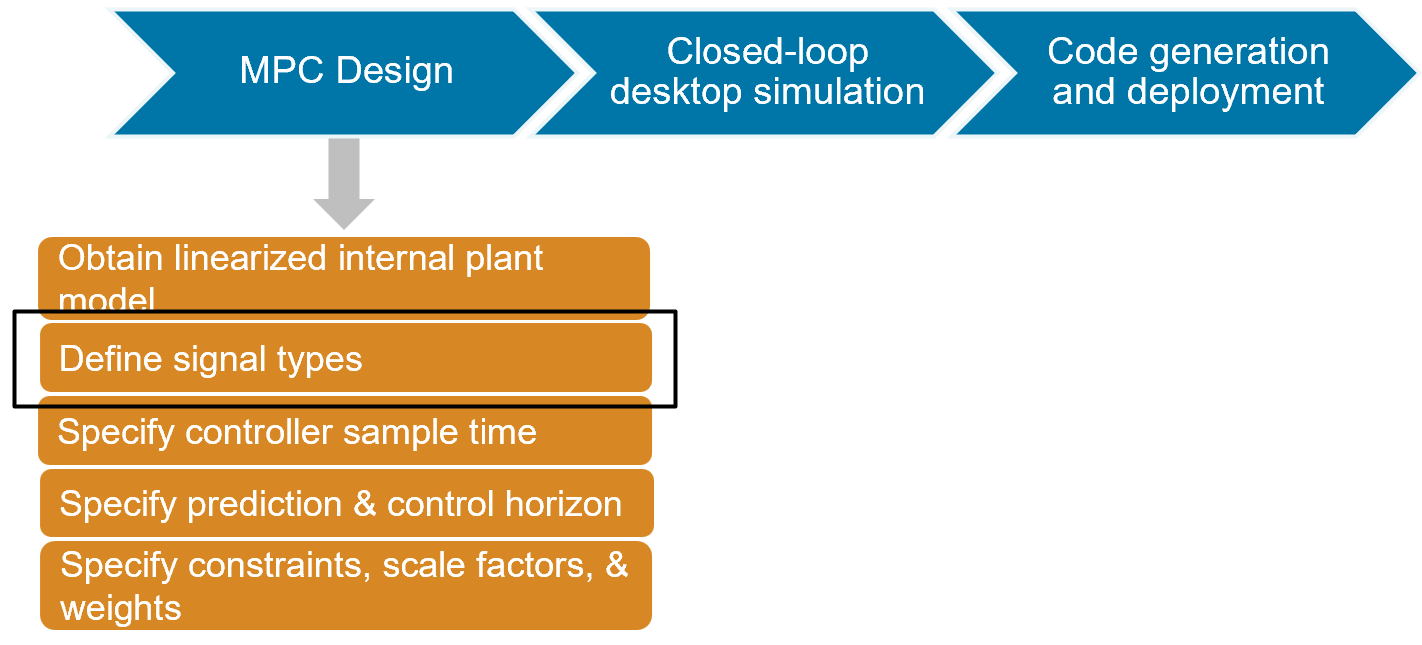

For MPC design purposes, signals are usually categorized into different input and output types. 

**Inputs:** The plant inputs are the independent variables affecting the plant. As shown in the figure below, there are three types: manipulated variables, measure disturbances, and unmeasured disturbances.

**Outputs: **The plant outputs are the dependent variables (outcomes) you wish to control or monitor. As shown in the figure below, there are two types: measured outputs and unmeasured outputs.

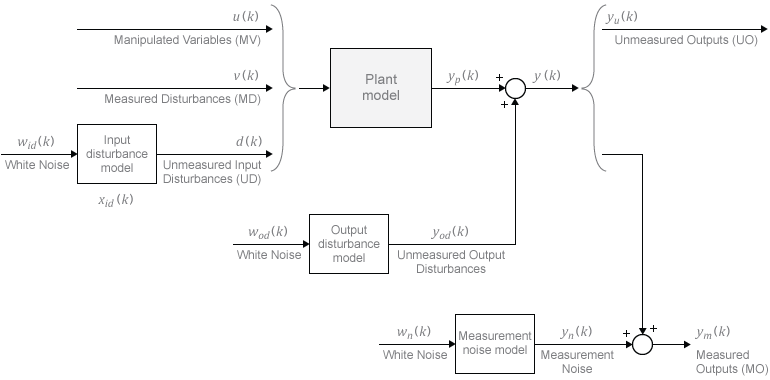

The plant has two inputs, *dF* and *F*, and two outputs, *x* and *theta*. What are the signal types for the plant?

- *dF *and* F *are manipulated variables.* x *and* theta* are unmeasured outputs.

- *dF *is an unmeasured disturbance and *F *is a manipulated variable.* x *and *theta* are measured outputs.

- *dF *is a manipulated variable and *F *is an unmeasured disturbance.* x *and* theta *are measured outputs.

signal_types =2;

Set the plant signal types using the setmpcsignals command. Please see this [link](https://www.mathworks.com/help/mpc/ref/setmpcsignals.html) for more information.

plant = setmpcsignals(plant,'ud',1,'mv',2);

## Specify Controller Sample Time, Prediction Horizon, and Control Horizon

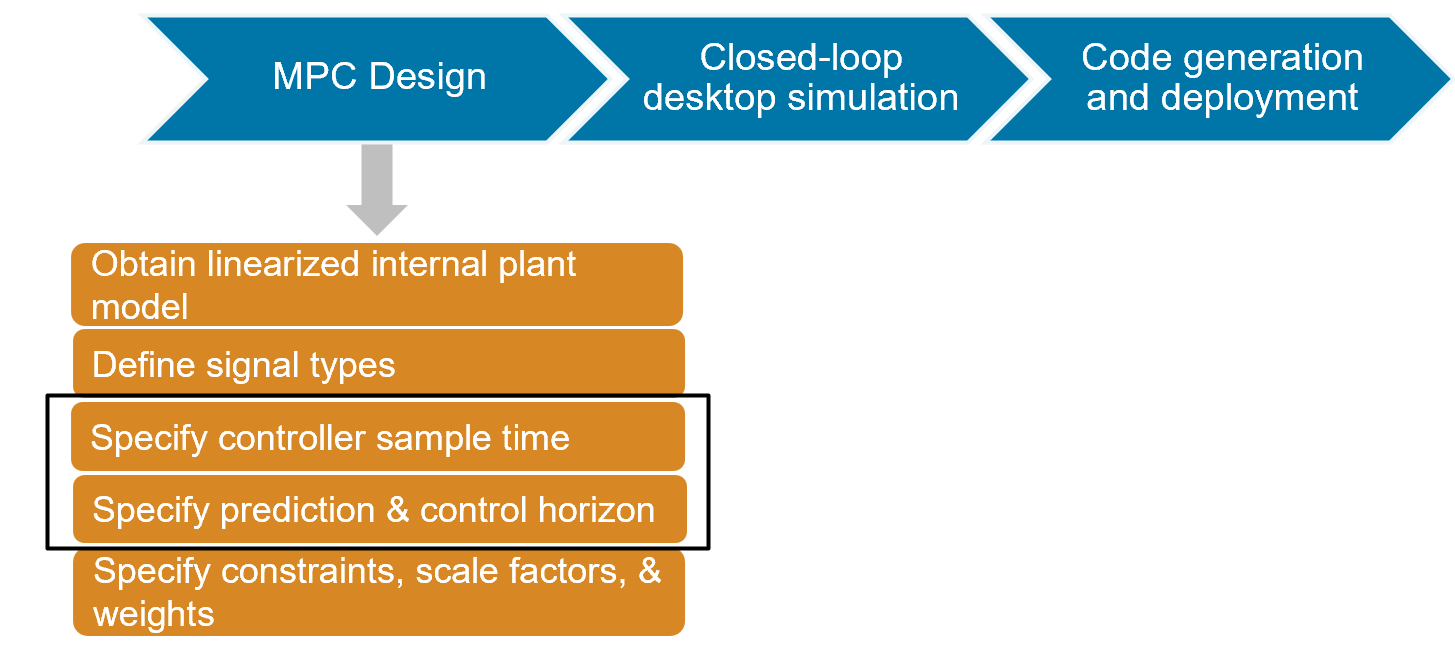

To control an unstable plant, the controller sample time cannot be too large (poor disturbance rejection) or too small (excessive computation load). Similarly, the prediction horizon cannot be too long (the plant unstable mode would dominate) or too short (constraint violations would be unforeseen). Use the following parameters for this example:

Ts = 0.01;
PredictionHorizon = 50;
ControlHorizon = 5;

More details regarding choosing sample time and horizons can be found [here](https://www.mathworks.com/help/mpc/ug/choosing-sample-time-and-horizons.html). Now we have all the pieces needed to create an MPC object. Please use the sample code below as reference and create an MPC object.

`mpcobj = mpc(plant,SampleTime,PredictionHorizon,ControlHorizon);`

mpcobj = mpc(plant,Ts,PredictionHorizon,ControlHorizon);

-->"Weights.ManipulatedVariables" is empty. Assuming default 0.00000.
-->"Weights.ManipulatedVariablesRate" is empty. Assuming default 0.10000.
-->"Weights.OutputVariables" is empty. Assuming default 1.00000.
   for output(s) y1 and zero weight for output(s) y2 


## Specify Constraints, Scale Factors, and Weights

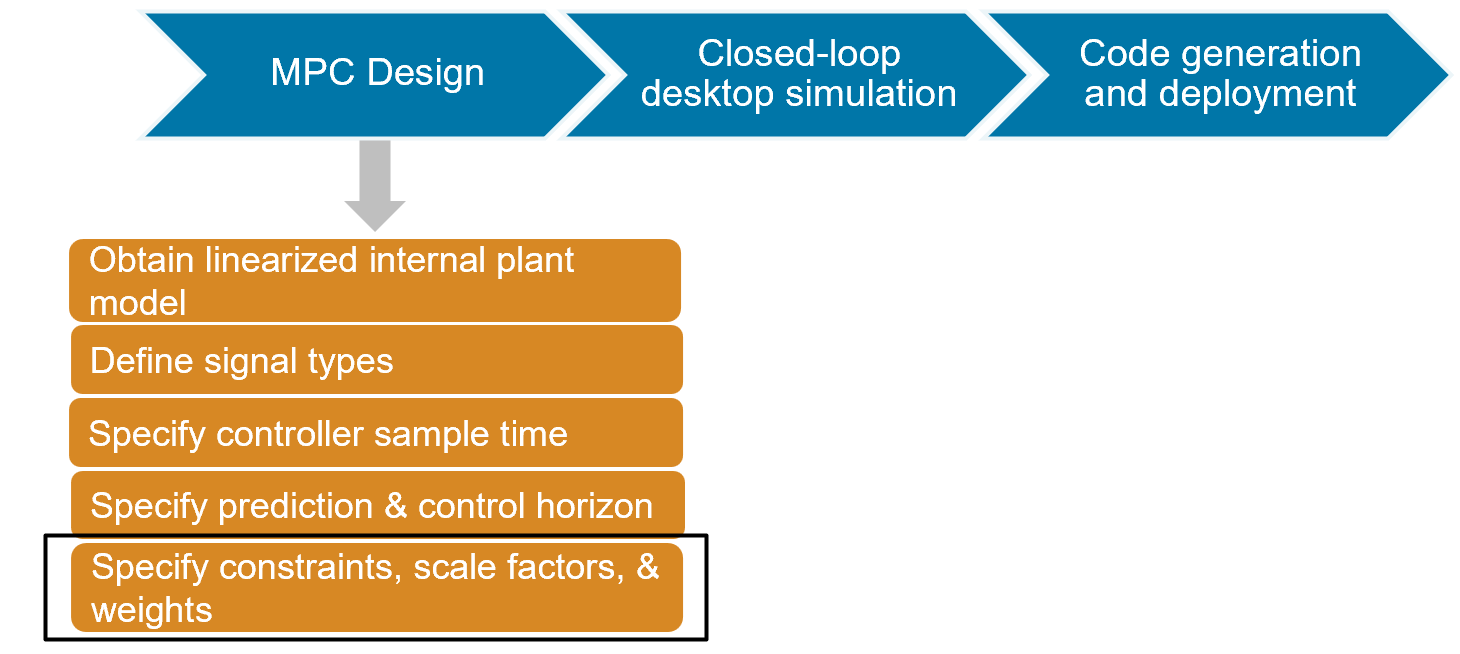

There is a limitation on how much force can be applied to the cart, which is specified as hard constraints on manipulated variable *F*. It has to between -200 and 200. Specify the constraints for the manipulated variable *F*. Use the following sample code and this [link](https://www.mathworks.com/help/mpc/ref/mpc.html#mw_bf8eacb6-b2f9-413c-bba5-67047fc5e78f) for reference:

`mpcobj.MV.Min = -8.5;`

`mpcobj.MV.Max = 8.5;`

mpcobj.MV.Min = -200;
mpcobj.MV.Max = 200;

#### Specify scale factors

Recommended practice includes specification of scale factors for each plant input and output variable, which is especially important when certain variables have much larger or smaller magnitudes than others.

The scale factor should equal (or approximate) the span of the variable. *Span* is the difference between its maximum and minimum value in engineering units, that is, the unit of measure specified in the plant model. Internally, MPC divides each plant input and output signal by its scale factor to generate dimensionless signals.

The potential benefits of scaling are as follows:

- Default MPC tuning weights work best when all signals are of order unity. Appropriate scale factors make the default weights a good starting point for controller tuning and refinement.

- When choosing cost function weights (which is what you will be doing next), you can focus on the relative priority of each term rather than a combination of priority and signal scale.

- Improved numerical conditioning. When values are scaled, round-off errors have less impact on calculations.

It is good practice to scale plant inputs and outputs before designing weights. In this case, since the range of the manipulated variable is greater than the range of the plant outputs by two orders of magnitude, scale the MV input by `100`. Please see these links on how to specify scale factors for [ManipulatedVariables](https://www.mathworks.com/help/mpc/ref/mpc.html#mw_bf8eacb6-b2f9-413c-bba5-67047fc5e78f) and [OutputVariables](https://www.mathworks.com/help/mpc/ref/mpc.html#mw_9f1182bf-1713-4958-a89d-07835dd3ce46). Use the sample code below to specify a scale factor of 100 for the manipulated variable.

`mpcobj.ManipulatedVariables.ScaleFactor = 10;`

mpcobj.ManipulatedVariables.ScaleFactor = 100;

#### Specify weights

The standard MPC cost function has 4 parts: output reference tracking, manipulated variable tracking, manipulated variable move suppression, and slack variable for soft constraints. Please see this [link](https://www.mathworks.com/help/mpc/ug/optimization-problem.html#bujxvp9-9) for more details. 

You can change the weights for each of these parts as explained in this [link](https://www.mathworks.com/help/mpc/ref/mpc.html#mw_a78e56e2-d2ba-4510-b96c-fc9ea69ba5bb).

To improve controller robustness, increase the weight on the MV rate of change from `0.1` to `1`. Try changing the weights and see how the performance of the controller changes.

mpcobj.Weights.MVRate = 1;

To achieve balanced performance, adjust the weights on the plant outputs. The first weight is associated with cart position *x* and the second weight is associated with angle *theta*.

mpcobj.Weights.OV = [1.2 1];

#### Disturbance models

To achieve more aggressive disturbance rejection, increase the state estimator gain by multiplying the default disturbance model gains by a factor of `10`.

Update the input disturbance model.

disturbance_model = getindist(mpcobj);

-->Converting model to discrete time.
-->The "Model.Disturbance" property is empty:
   Assuming unmeasured input disturbance #1 is integrated white noise.
   Assuming no disturbance added to measured output #1.
-->Assuming output disturbance added to measured output #2 is integrated white noise.
-->"Model.Noise" is empty. Assuming white noise on each measured output.


setindist(mpcobj,'model',disturbance_model*10);

Update the output disturbance model.

disturbance_model = getoutdist(mpcobj);

-->Converting model to discrete time.
   Assuming no disturbance added to measured output #1.
-->Assuming output disturbance added to measured output #2 is integrated white noise.
-->"Model.Noise" is empty. Assuming white noise on each measured output.


setoutdist(mpcobj,'model',disturbance_model*10);

## Closed-Loop Simulation

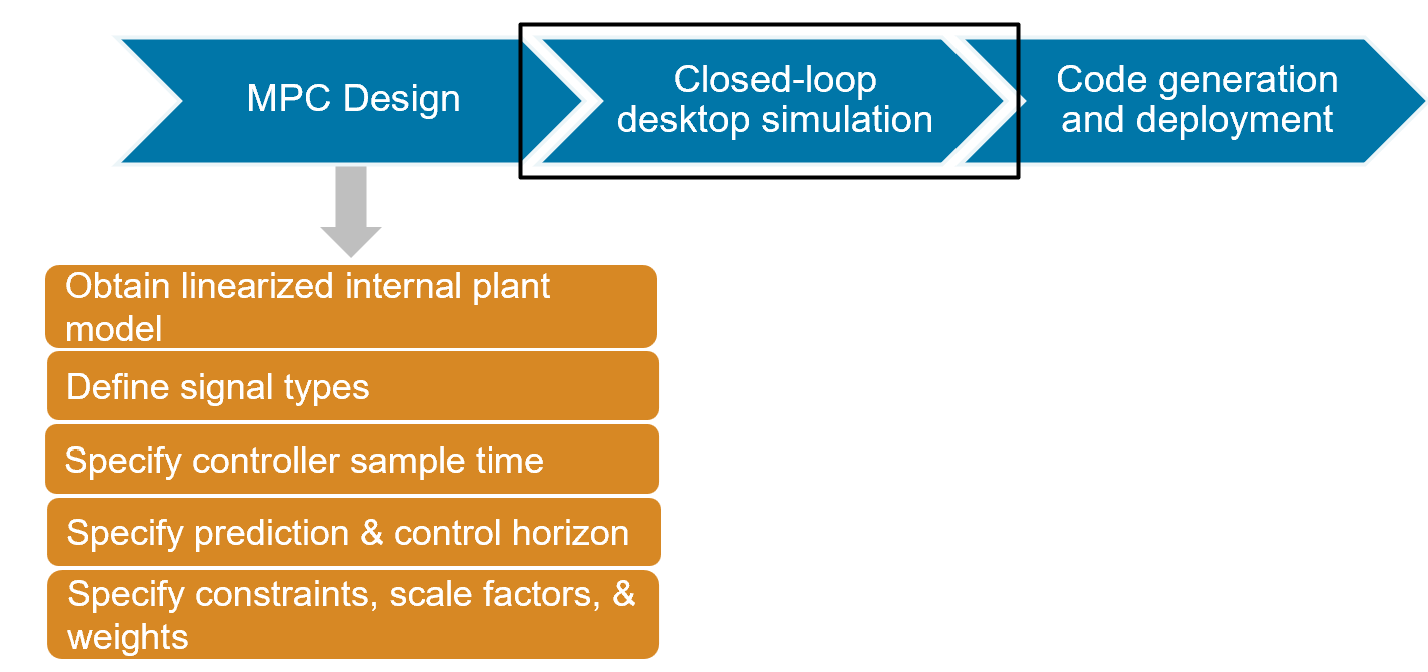

Validate the MPC design with a closed-loop simulation in Simulink.

-->Converting model to discrete time.
-->"Model.Noise" is empty. Assuming white noise on each measured output.


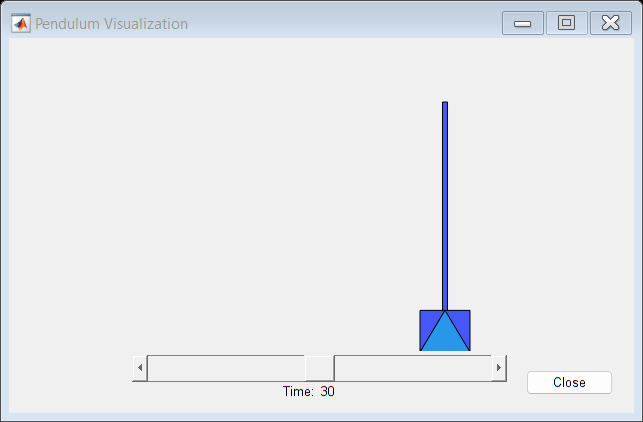

open_system([mdlMPC '/Scope']);
sim(mdlMPC);

In the nonlinear simulation, all the control objectives are successfully achieved.

## Discussion

It is important to point out that the designed MPC controller has its limitations. For example, if you increase the step setpoint change to `15`, the pendulum fails to recover its upright position during the transition.

To reach the longer distance within the same rise time, the controller applies more force to the cart at the beginning. As a result, the pendulum is displaced from its upright position by a larger angle such as `60` degrees. At such angles, the plant dynamics differ significantly from the LTI predictive model obtained at *theta* = `0`. As a result, errors in the prediction of plant behavior exceed what the built-in MPC robustness can handle, and the controller fails to perform properly.

A simple workaround to avoid the pendulum falling is to restrict pendulum displacement by adding soft output constraints to theta and reducing the ECR weight on constraint softening.

However, with these new controller settings, it is no longer possible to reach the longer distance within the required rise time. In other words, controller performance is sacrificed to avoid violation of soft output constraints.

To reach longer distances within the same rise time, the controller needs more accurate models at different angle to improve prediction. Another [example](https://www.mathworks.com/help/mpc/ug/gain-scheduled-mpc-control-of-an-inverted-pendulum-on-a-cart.html) shows how to use gain scheduling MPC to achieve the longer distances.

You can close the Simulink model using the command below.

`bdclose(mdlMPC)`

## Code Generation and Deployment

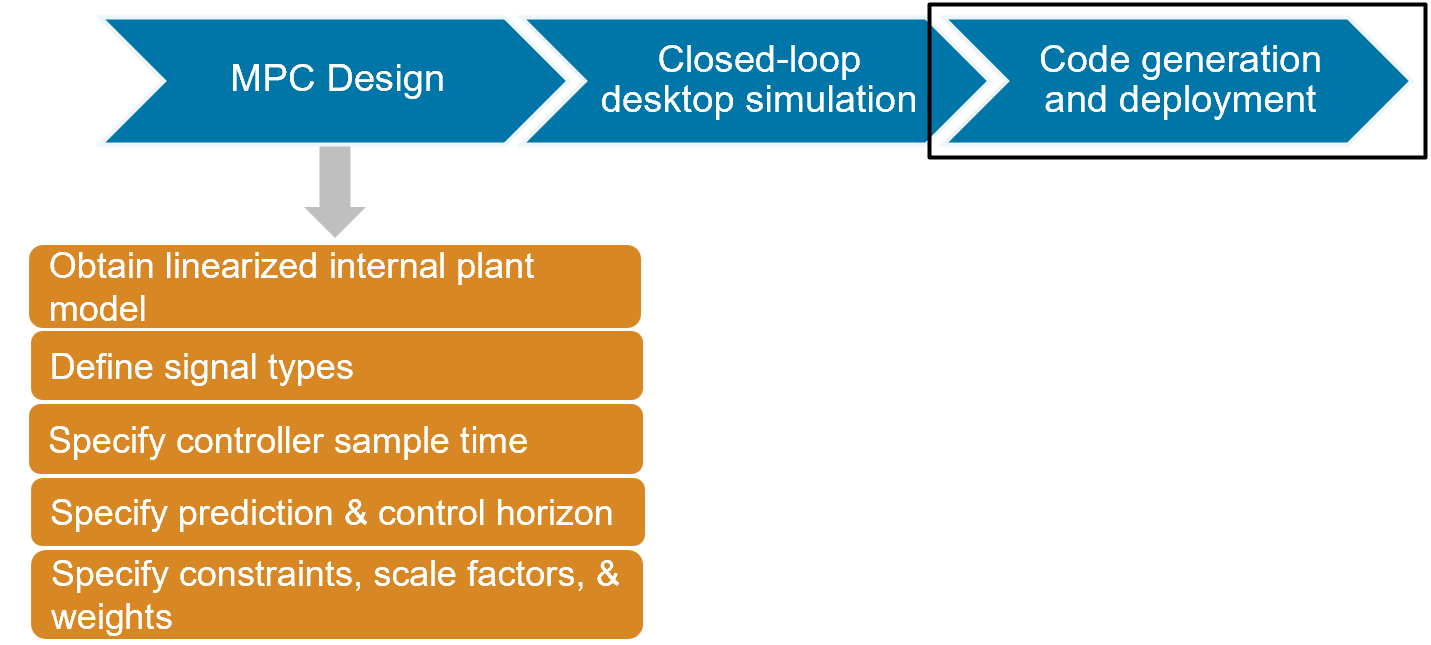

Once you are satisified with the performance of the controller, the last step is to generate code and deploy the designed controller. Please see this [link](https://www.mathworks.com/help/mpc/ug/generate-code-and-deploy-controller-to-real-time-targets.html) for details.

*Copyright 1986-2023 The MathWorks, Inc.*